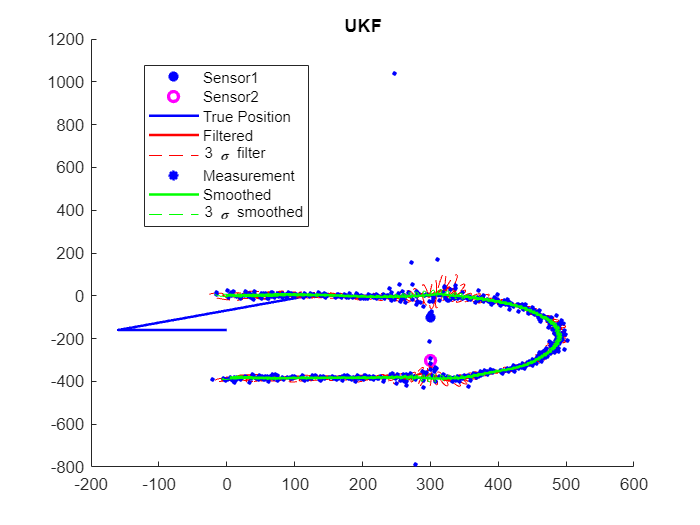

clear;
clc;
close all;

%Given
T = 0.1;
K = 600;
omega = zeros(1,K+1);
omega(150:450) = -pi/301/T;
x0 = [0 0 20 0 omega(1)]';
X = zeros(length(x0),K+1);
X(:,1) = x0;

for i = 2:K+1
    if i ==300
    X(:,i) = 1.1*coordinatedTurnMotion(X(:,i-1),T);
    X(5,i) = 1.1*omega(i);
    else
    X(:,i) = coordinatedTurnMotion(X(:,i-1),T);
    X(5,i) = omega(i);
    end
end

%tuned value from HA3
sigma_v = 10;
sigma_w = pi/180*6;


x_0 = [0 0 0 0 0]';
P_0 = diag([10 10 10 5*pi/180 pi/180].^2);
s1 = [300 -100];
s2 = [300 -300];
S=[s1;s2];
% S = cat(3, s1, s2);
R = diag([pi/180 pi/180].^2);

gama=[0 0; 0 0; 1 0; 0 0; 0 1];
Q = gama *[sigma_v^2 0; 0 sigma_w^2]*gama';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% f = @(x) coordinatedTurnMotion(x, T) ;
measModel = @(x,s) dualBearingMeasurement(x, s) ;%modified dualBearingMeasurement function, that can input S matrix now

% Motion model
motionModel = @coordinatedTurnMotion;
% Measurement model
% measModel = @(x,s) rangeBearingMeasurements (x,S);%Attention: S here is 2x1 vector

% Generate state sequence and measurement sequence
% X = genNonLinearStateSequence(x_0, P_0, f, Q, K);
Y = genNonLinearMeasurementSequence(X, measModel, R,S);%add a S her


% [xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,'UKF',S, sigmaPoints);

% function handle for generating sigma points
genSigmaPoints = @sigmaPoints;

[xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, motionModel, T, Q, S, measModel, R, genSigmaPoints, 'UKF');

%   xf          [n x N]     Filtered estimates for times 1,...,N
%   Pf          [n x n x N] Filter error convariance
%   xp          [n x N]     Predicted estimates for times 1,...,N
%   Pp          [n x n x N] Filter error convariance
%   xs          [n x N]     Smoothed estimates for times 1,...,N
%   Ps          [n x n x N] Smoothing error convariance

figure;
hold on;
% Sensor position
h1= plot(s1(1), s1(2), '*b', 'Linewidth', 2);
h2= plot(s2(1), s2(2), 'om', 'Linewidth', 2);
% Plot true positions
h3= plot(X(1,:), X(2,:), 'b-', 'LineWidth', 1.5);

% Plot Filters states
h4= plot(xf(1,:), xf(2,:), 'r-', 'LineWidth', 1.5);
% 3 sigma for filtered

for i = 1:5:length(xf)
    xy = sigmaEllipse2D(xf(1:2,i), Pf(1:2,1:2,i), 3, 50);
    h5= plot(xy(1,:), xy(2,:), '--r');
end

% Plot Dual bearing measurements
sensorx = (s2(2)-s1(2)+tan(Y(1,:))*s1(1)-tan(Y(2,:))*s2(1))./(tan(Y(1,:))-tan(Y(2,:)));
sensory = s1(2) + tan(Y(1,:)) .* (sensorx - s1(1));
h6 = scatter(sensorx, sensory, 5, 'b*', 'LineWidth', 1.5);

% Plot Smoothed states
h7 = plot(xs(1,:), xs(2,:), 'g', 'LineWidth', 1.5);
% 3 sigma for smoothed
for i = 1:5:length(xs)
    xys = sigmaEllipse2D(xs(1:2,i), Ps(1:2,1:2,i), 3, 50);
    h8 = plot(xys(1,:), xys(2,:), '--g');
end

% Create overall legend
legend([h1,h2,h3,h4,h5,h6,h7,h8],{'Sensor1', 'Sensor2', 'True Position', 'Filtered', '3 \sigma filter', 'Measurement', 'Smoothed', '3 \sigma smoothed'},'Location','best');
title('UKF')